## Part 4

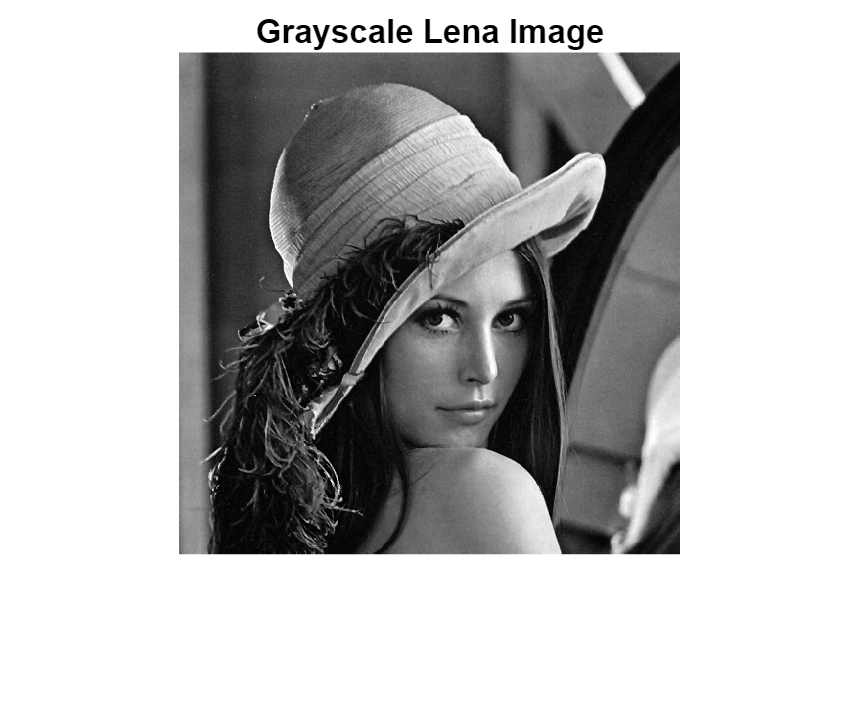

clear
close all
warning('off','all')

%Load and display grayscale 'Lena' image file
img = rescale(im2gray(imread('img_gray.png')));
imshow(img)
title('Grayscale Lena Image')

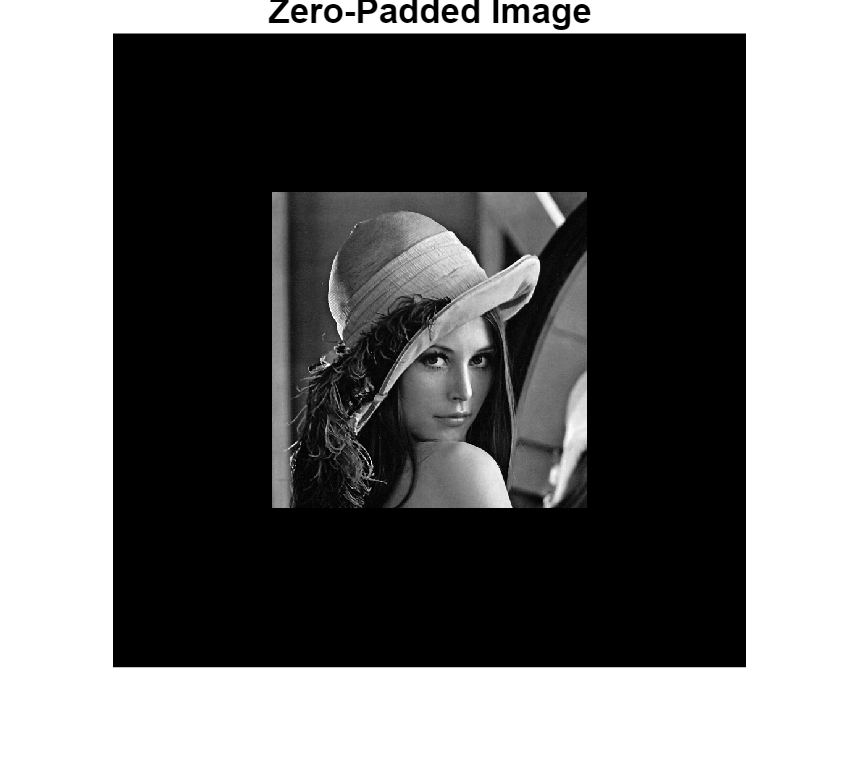


%Remove first row and column of img to create an array with odd dimensions
%Going from 512 x 512 to 511 x 511
img(1,:) = [];
img(:,1) = [];

%Pad image with zeros to produce new image of dimension (2^p + 1) x (2^p + 1)
%In this case, p=10 and padded img is 1025 x 1025
padding = ((2^10) + 1 - size(img,1))/2;
img_pad = padarray(img, [padding, padding]);

%Display padded image
imshow(img_pad)
title('Zero-Padded Image')

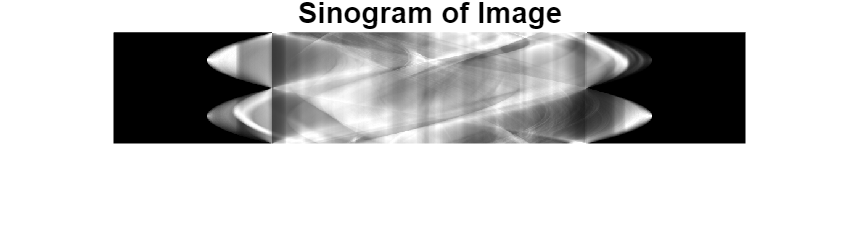


%Set rotation angle step to 1 degree
del_phi = 1;

%Define projection matrix
p_phi = [];

%Simulate projections by rotating img and summing down columns
for phi_temp = 0:del_phi:179
    img_temp = imrotate(img_pad, phi_temp, 'crop');
    p_phi(phi_temp+1, :) = sum(img_temp);
end

%Display normalized projection matrix (sinogram)
imshow(p_phi./max(p_phi))
title('Sinogram of Image')

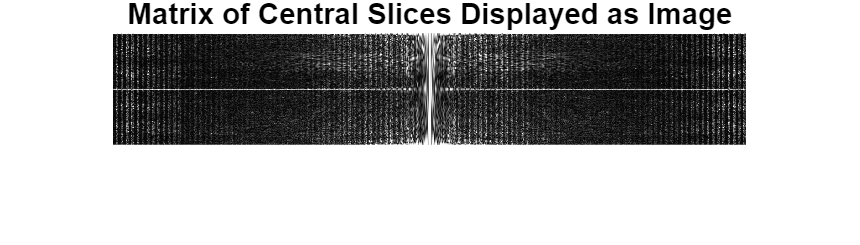


%Remove last column of proj mtx so 2nd dimension = 2^10
p_phi(:,2^10 + 1) = [];

%Perform fftshift followed by 1D fft (central slices)
p_phi = fftshift(p_phi, 2);
P_phi = fft(p_phi,[],2);
P_phi = fftshift(P_phi, 2);

%Display normalized central slice matrix
imshow(abs(P_phi)./max(abs(P_phi)))
title('Matrix of Central Slices Displayed as Image')

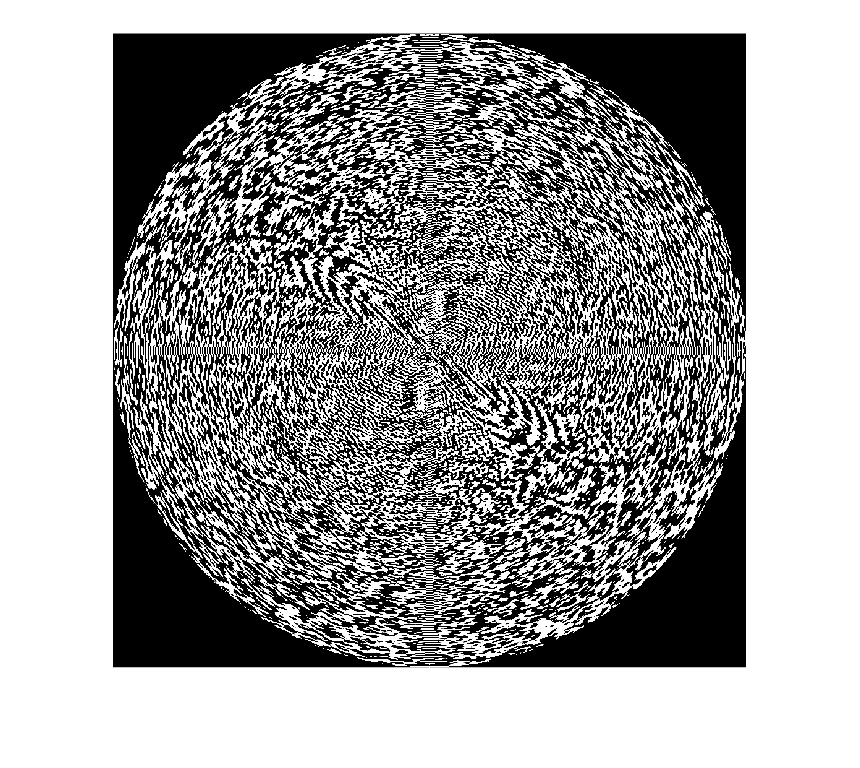


%Create arrays for use in griddata
phi = [0:1:179]';
omega_x_prime = [-size(P_phi,2)/2 : 1 : size(P_phi,2)/2 - 1];
omega_x_known = cosd(phi)*omega_x_prime;
omega_y_known = sind(phi)*omega_x_prime;
values_known = P_phi;
omega_x_target = ones(size(omega_x_prime,1),1)'*omega_x_prime;
omega_y_target = omega_x_target';

%Estimate F with linear interpolation of central slices
F_lin = griddata(omega_x_known,omega_y_known,values_known,omega_x_target,omega_y_target,'linear');

%Replace NaN values with 0
NaNs = isnan(F_lin);
F_lin(NaNs) = 0;

%Estimate F with nearest neighbor interpolation of central slices
F_near = griddata(omega_x_known,omega_y_known,values_known,omega_x_target,omega_y_target,'nearest');

%Replace NaN values with 0
NaNs = isnan(F_near);
F_near(NaNs) = 0;

%Estimate F with cubic interpolation of central slices
F_cub = griddata(omega_x_known,omega_y_known,values_known,omega_x_target,omega_y_target,'cubic');

%Replace NaN values with 0
NaNs = isnan(F_cub);
F_cub(NaNs) = 0;

%Display real part of F w/ linear interpolation
imshow(F_lin)
title('')

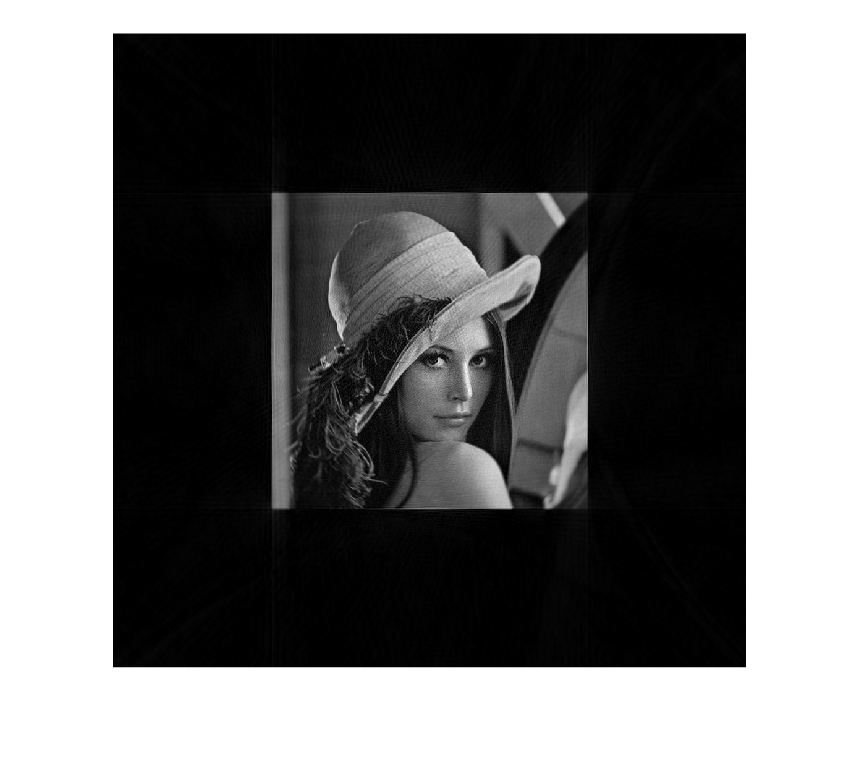


%Estimate f using 2D ifft of F for each interpolation type
f_lin = fftshift(ifft2(fftshift(F_lin)));
f_near = fftshift(ifft2(fftshift(F_near)));
f_cub = fftshift(ifft2(fftshift(F_cub)));

%Display magnitude of f w/ linear interpolation
imshow(rescale(abs(f_lin)))

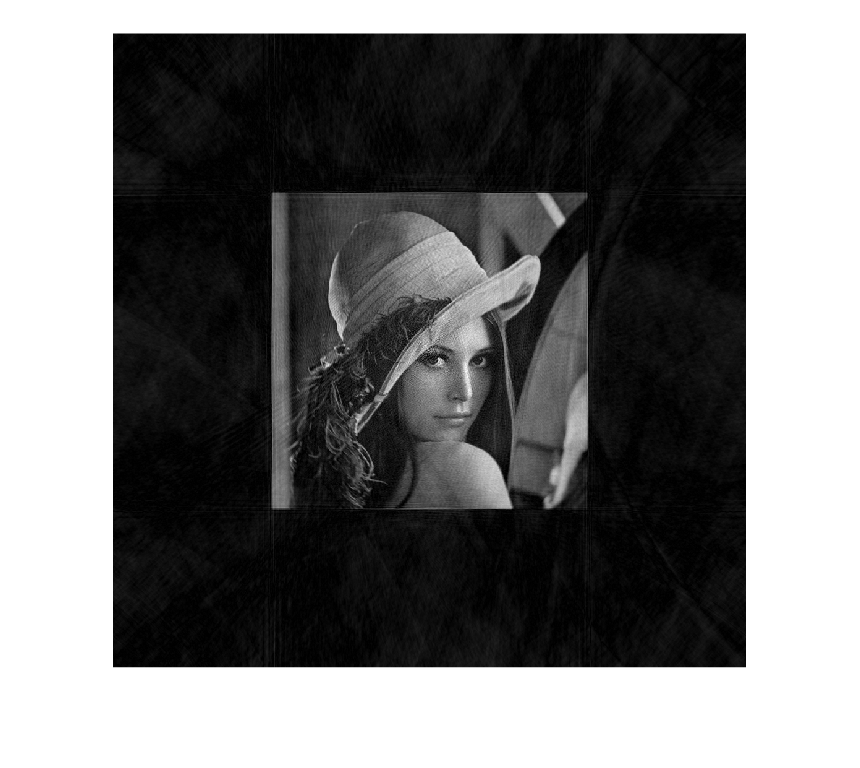


%Display magnitude of f w/ nearest neighbor interpolation
imshow(rescale(abs(f_near)))

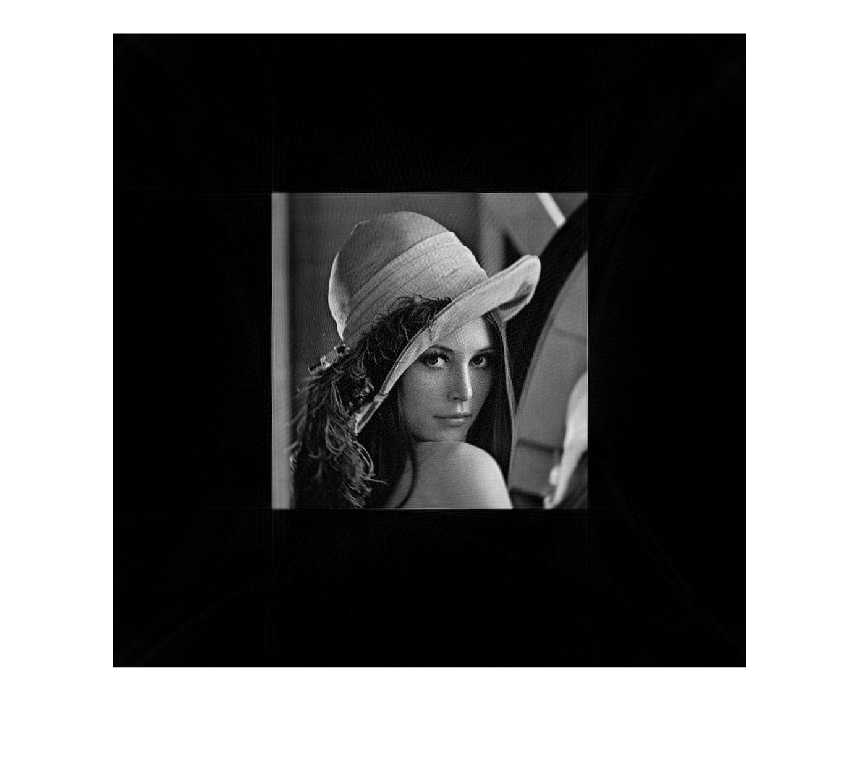


%Display magnitude of f w/ linear interpolation
imshow(rescale(abs(f_cub)))

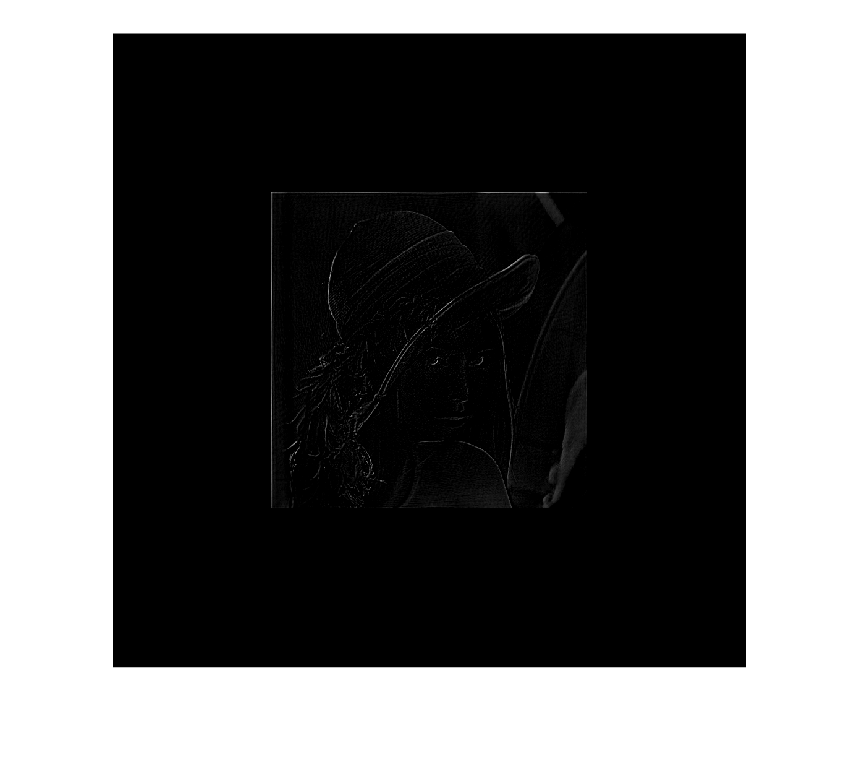


%Remove 1st row and column of zeros in original padded image
%so the dimensions will match with reconstructed images
img_pad(1,:) = [];
img_pad(:,1) = [];

%Calculate error magnitude matrix of reconstructed images for each interpolation type
err_lin = double(img_pad) - abs(f_lin);
err_cub = double(img_pad) - abs(f_cub);
err_near = double(img_pad) - abs(f_near);

%Display error magnitude plots for each interpolation type
imshow(err_lin)

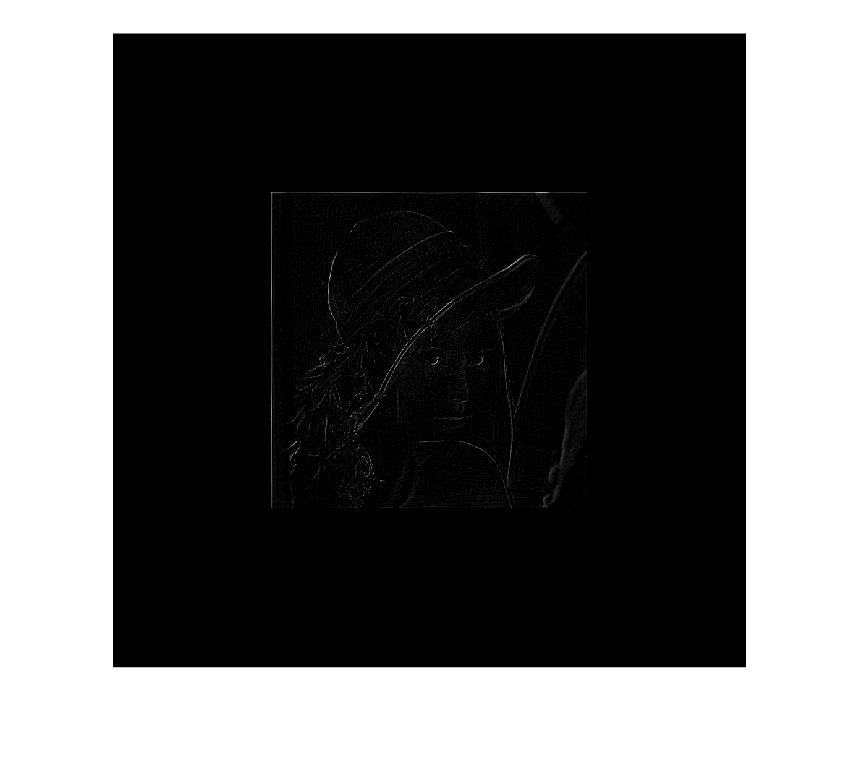

imshow(err_cub)

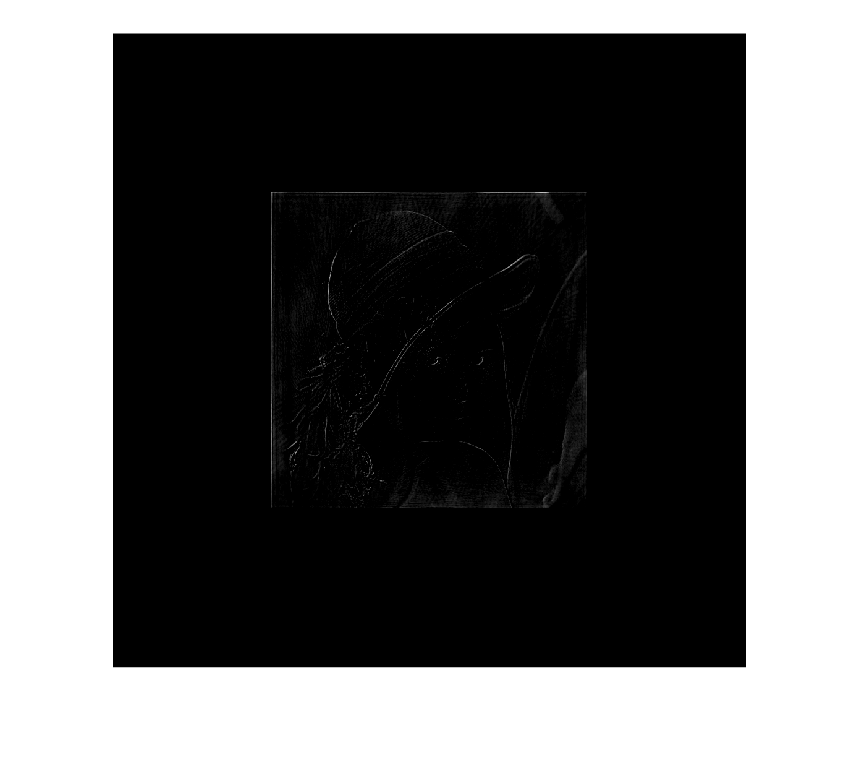

imshow(err_near)


%Calculate mean squared error (MSE) between each reconstruction and original img
mse_lin = immse(double(img_pad), f_lin);
mse_cub = immse(double(img_pad), f_cub);
mse_near = immse(double(img_pad), f_near);

%Print MSEs
fprintf('\n The mean-squared error for linear interpolation is %0.4f\n \n The mean-squared error for cubic interpolation is %0.4f\n \n The mean-squared error for nearest neighbor interpolation is %0.4f\n', mse_lin, mse_cub, mse_near);


 The mean-squared error for linear interpolation is 0.0017
 
 The mean-squared error for cubic interpolation is 0.0016
 
 The mean-squared error for nearest neighbor interpolation is 0.0050
